# Data Processing Course Example

pfa = "1e-6";

scenario = helperCreateScenario(pfa);
[tp, platp, detp, covp] = helperCreatePlotters();

Create Tracker Plotter

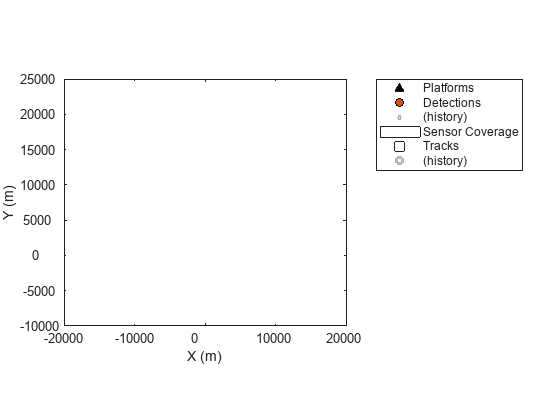

trackPlot = trackPlotter(tp,"DisplayName","Tracks","HistoryDepth",500);

## Create Tracker

tracker = trackerGNN("AssignmentThreshold",500,"FilterInitializationFcn","initekfimm");

## Update Simulation Loop

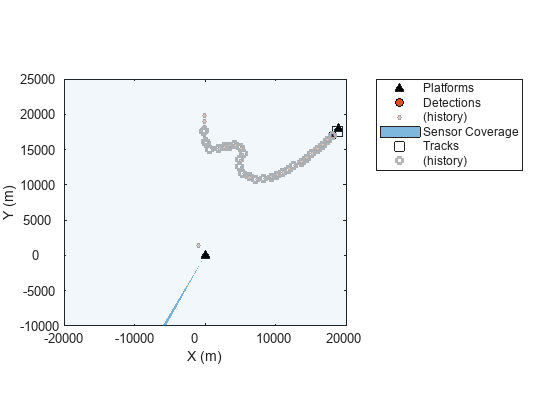

detectionVector = [];
while advance(scenario)
    % update platforms
    truePoses = platformPoses(scenario);
    position = vertcat(truePoses(:).Position);
    plotPlatform(platp,position)

    % generate detection data
    [dets,sensorConfig] = detect(scenario);
    detectionVector = [detectionVector dets{:}];
    %if ~isempty(detectionVector)
    if sensorConfig.IsScanDone
        % extract column vector of measurement positions
        meas = cat(2,detectionVector.Measurement)';
        % extract measurement noise
        measCov = cat(3,detectionVector.MeasurementNoise);
        % plot detections
        plotDetection(detp,meas)
        % Update tracker with detections from this scan
        [tracks,tentative,allTracks,info] = tracker(detectionVector(:),scenario.SimulationTime);
        % Plot current track state
        plotTrack(trackPlot,getTrackPositions(tracks,[1 0 0 0 0 0; 0 0 1 0 0 0; 0 0 0 0 1 0]))
        % USE THIS FOR CONSTANT ACCELERATION MODEL
        %plotTrack(trackPlot,getTrackPositions(tracks,[1 0 0 0 0 0 0 0 0; 0 0 0 1 0 0 0 0 0; 0 0 0 0 0 0 1 0 0]))
        detectionVector = [];
    end
    plotCoverage(covp,coverageConfig(scenario))
end

function [tp,platp,detp,covp] = helperCreatePlotters
% Create plotters
tp = theaterPlot("XLim",[-20e3 20e3],"YLim",[-10e3 25e3],"ZLim",[0e3 10e3]);
platp = platformPlotter(tp,"DisplayName","Platforms","MarkerFaceColor","k");
detp = detectionPlotter(tp,"DisplayName","Detections","MarkerSize",6,...
    "MarkerFaceColor",[0.85 0.325 0.098],"MarkerEdgeColor","k","History",10000);
covp = coveragePlotter(tp,"DisplayName","Sensor Coverage");
end


function scenario = helperCreateScenario(pfa)
% Create Scenario
scenario = trackingScenario;
scenario.UpdateRate = 0;

% Create platforms
BoatCenter = platform(scenario);

Plane = platform(scenario);
Plane.Trajectory = waypointTrajectory( ...
    [0 20000 2000; 0 17000 2000; 1000 15000 2500; 5000 15000 2500; ...
    5000 12500 2000; 9500 11000 3000; 18998 17952 2880], ...
    [0; 12; 22; 40; 50; 70; 114], ...
    "GroundSpeed",[250;250;250;250;250;250;250], ...
    "AutoPitch",true, ...
    "AutoBank",true);


% Create sensors
BoatRotator = radarDataGenerator("SensorIndex",1, ...
    "UpdateRate",50, ...
    "MountingAngles",[0 0 0], ...
    "DetectionProbability",0.95, ...
    "FalseAlarmRate",str2double(pfa), ...
    "FieldOfView",[2 30], ...
    "HasINS",true, ...
    "DetectionCoordinates","Scenario",...
    "MaxAzimuthScanRate",120, ...
    "TargetReportFormat","Detections");


% Assign sensors to platforms
BoatCenter.Sensors = BoatRotator;
end

function filter = FilterInit(detection)
filter = initcvekf(detection);
classToUse = class(filter.StateCovariance);

Airliners can move at speeds of around 900 km/h. The velocity is initialized to 0, but will need to be able to quickly adapt to aircraft moving at these speeds. Use 900 km/h as 1 standard deviation for the initialized track's velocity noise.

spd = 900*1e3/3600; % m/s
velCov = cast(spd^2,classToUse);
cov = filter.StateCovariance;
cov(2,2) = velCov;
cov(4,4) = velCov;
filter.StateCovariance = cov;

% Set filter's process noise to match filter's update rate
scaleAccelHorz = cast(1,classToUse);
scaleAccelVert = cast(1,classToUse);
Q = blkdiag(scaleAccelHorz^2,scaleAccelHorz^2,scaleAccelVert^2);
filter.ProcessNoise = Q;
end
